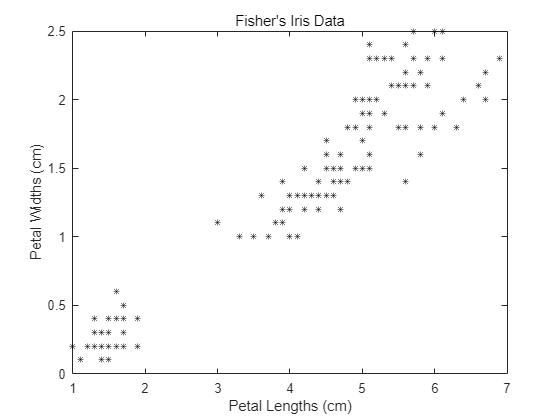

load fisheriris
X = meas(:,3:4);
figure;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)';
ylabel 'Petal Widths (cm)';

## 2. Cluster the data using kmeans. Specify k = 3 clusters.

rng(1); % For reproducibility
[idx,C] = kmeans(X,3);
x1 = min(X(:,1)):0.01:max(X(:,1));
x2 = min(X(:,2)):0.01:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot
idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C);

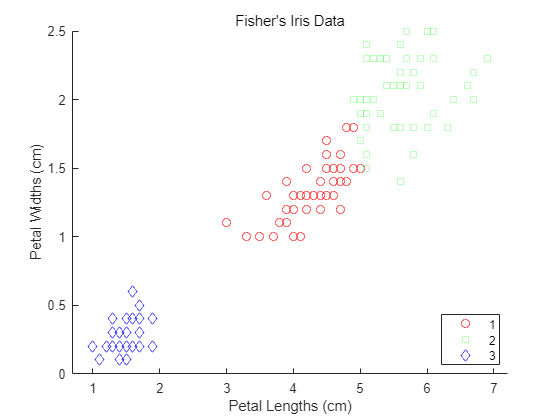


figure;
hold on;
%gscatter(XGrid(:,1),XGrid(:,2),idx2Region, [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
gscatter(X(:,1),X(:,2),idx, 'rgb','osd');
%plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)';
ylabel 'Petal Widths (cm)';
%legend('Region 1','Region 2','Region 3','Data','Location','Best');
hold off;

rng(1); % For reproducibility
[idx,C] = kmeans(X,3, 'Distance','cityblock'); % Using 'cityblock' distance
x1 = min(X(:,1)):0.01:max(X(:,1));
x2 = min(X(:,2)):0.01:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot
idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C, 'Distance','cityblock'); % Also use 'cityblock' here

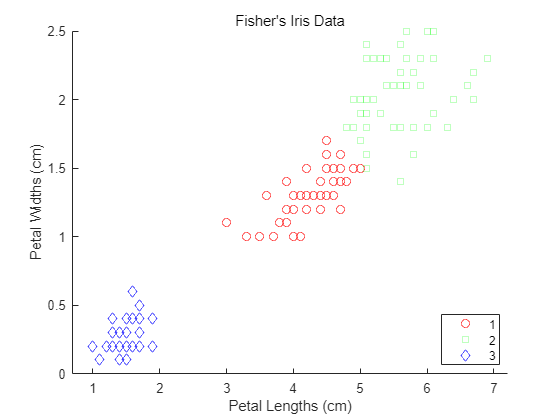


figure;
hold on;
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region, [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
gscatter(X(:,1),X(:,2),idx, 'rgb','osd');
% plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)';
ylabel 'Petal Widths (cm)';
% legend('Region 1','Region 2','Region 3','Data','Location','Best');
hold off;

## 3. Clustering using hierarchical clustering

%Load the sample data.
load fisheriris
%Compute four clusters of the fisheriris data using single-linkage
Z = linkage(meas(:,3:4),'single','euclidean'); %create the linkage tree using single-
%link
c = cluster(Z,'maxclust',3);
% See how the cluster assignments correspond to the three species.
crosstab(c, species)

ans =      0     1     0
     0    49    50
    50     0     0


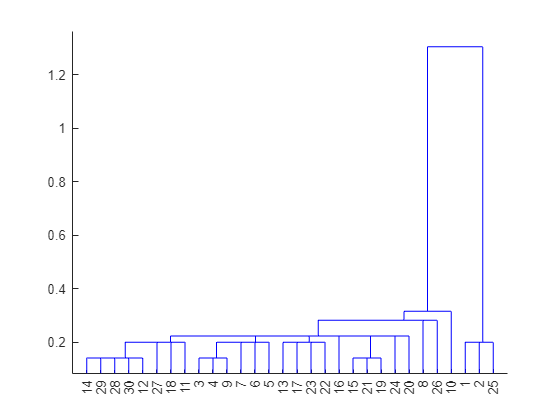

% Create a dendrogram plot of Z, and visualize it.
dendrogram(Z)

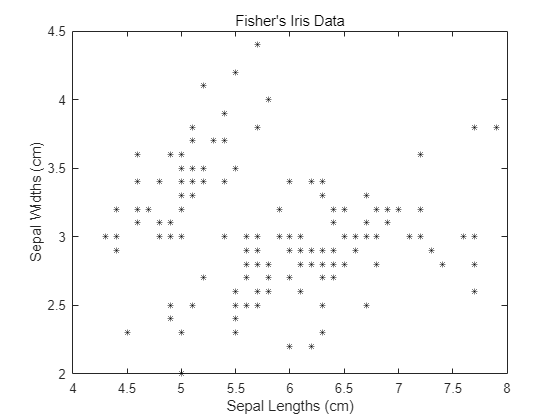

load fisheriris
X = meas(:,1:2); 
figure;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Sepal Lengths (cm)';
ylabel 'Sepal Widths (cm)';


% 2. 使用 k-均值聚类
rng(1); 
[idx,C] = kmeans(X,3);
x1 = min(X(:,1)):0.01:max(X(:,1));
x2 = min(X(:,2)):0.01:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; 
idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C);

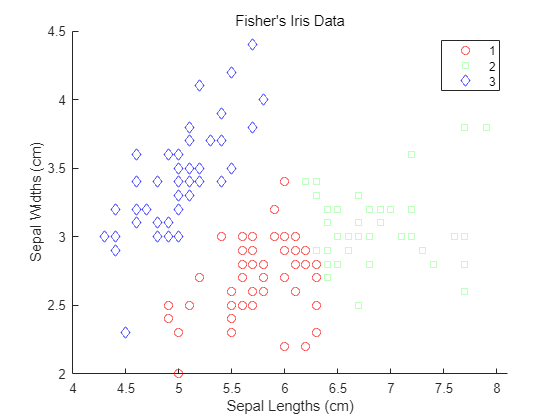


figure;
hold on;
gscatter(X(:,1),X(:,2),idx, 'rgb','osd');
title 'Fisher''s Iris Data';
xlabel 'Sepal Lengths (cm)';
ylabel 'Sepal Widths (cm)';
hold off;


rng(1); 
[idx,C] = kmeans(X,3, 'Distance','cityblock'); 
x1 = min(X(:,1)):0.01:max(X(:,1));
x2 = min(X(:,2)):0.01:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)];
idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C, 'Distance','cityblock'); 

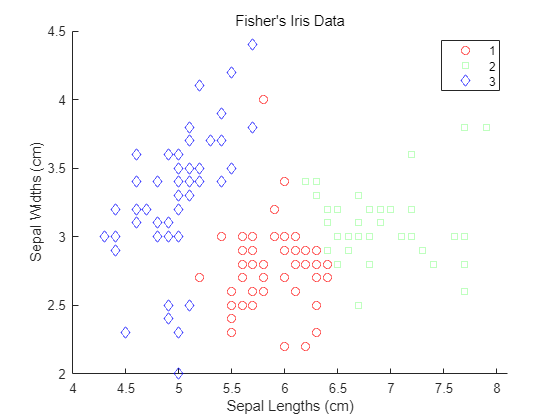


figure;
hold on;
gscatter(X(:,1),X(:,2),idx, 'rgb','osd');
title 'Fisher''s Iris Data';
xlabel 'Sepal Lengths (cm)';
ylabel 'Sepal Widths (cm)';
hold off;


% 3. 使用层次聚类
load fisheriris
Z = linkage(meas(:,1:2),'single','euclidean');
c = cluster(Z,'maxclust',3);
crosstab(c, species)

ans =      1     0     0
    49    50    48
     0     0     2


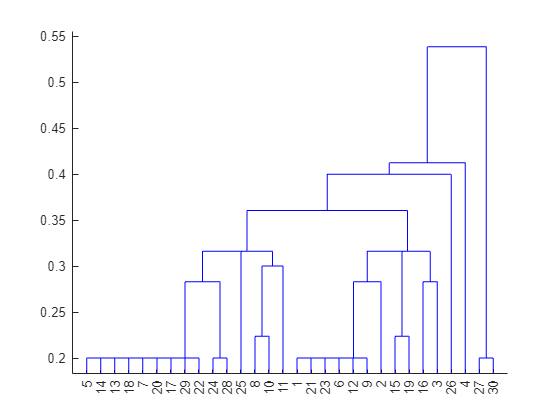

dendrogram(Z)